# Asquire

Task**:  Validation of Asquire Data (VAD)**

audio_files = dir("grouped_unpackd_audio/breath");
audio_files(1:2)=[]

audio_files = 73×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


#### **Fricatives**

#### 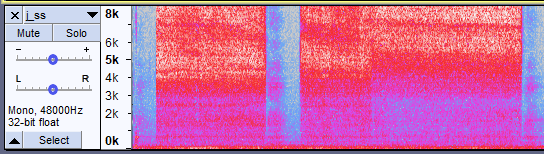 

Fig.1 example spectrum for "sss"

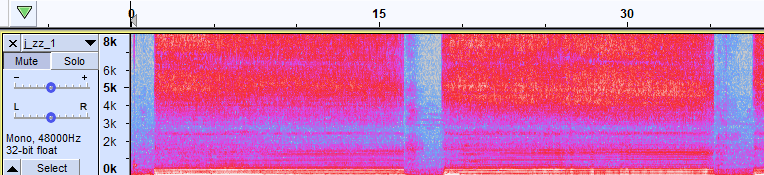

Fig.2 example spectrum for "zzz"

Obv: **High energy at 5k to 6k**

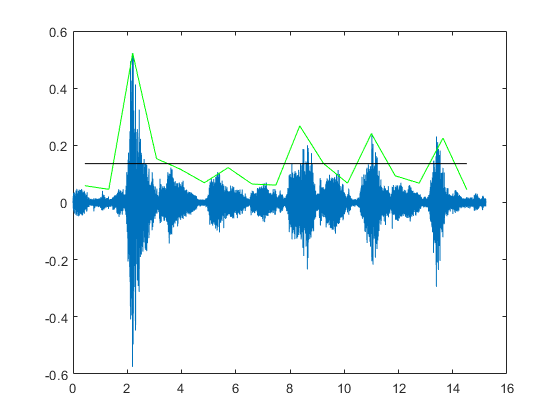

count_fric = 5

audio_file = audio_files(1).name;

startFreq = 50;
endFreq   = 6000;
engwinp   = 0.88;
thrp      = 0.26;

r.start = startFreq;
r.end = endFreq;

count_fric = countStimsL(audio_file, r, engwinp, thrp)

#### **Vowels**

- **"aaa" and others**

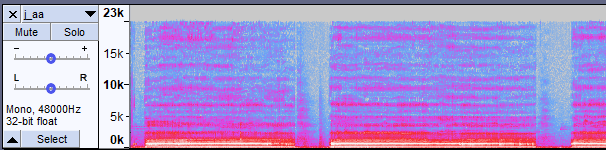

Fig.3 example spectrum for "aaa"

Obv: **High energy at 200 to 1k**

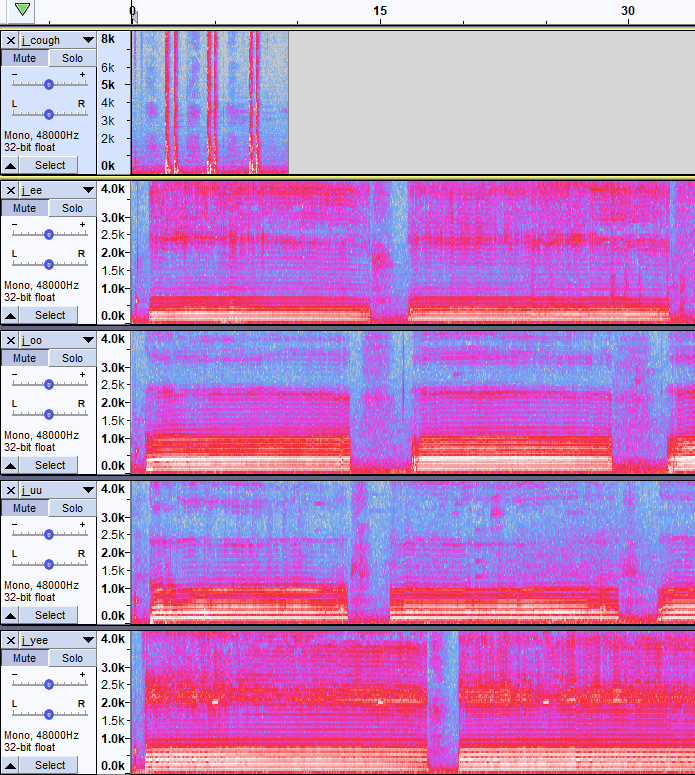

Fig.4 example spectrum for other vowels

Obv: **High energy at 200 to 1k**

audio_file = audio_files(1).name;

startFreq = 200;
endFreq   = 5000;
engwinp   = 0.74;
thrp      = 0.38;

r.start = startFreq;
r.end = endFreq;

count_vowel = countStimsL(audio_file, r, engwinp, thrp)

**Loop through**

all_fns = {audio_files(:).name};

audio_file = audio_files(1).name;

startFreq = 200;
endFreq   = 700;
engwinp   = 0.9;
thrp      = 0.2;

r.start = startFreq;
r.end = endFreq;


count_arr = zeros(3, length(all_fns));
for k=1:length(all_fns)
    filename = all_fns{k};
    t = split(filename, "_");
    t = t{length(t)};
    t = split(t, ".");
    t = t{1};
    true_count = str2double(t);
    detect_count = countStimsL(filename, r, engwinp, thrp);
    count_arr(1, k) = detect_count;
    count_arr(2, k) = true_count;
    % count_arr(3, k) = filename;
end

count_arr(3, :) = abs(count_arr(1, :) - count_arr(2, :))
res = find(count_arr(3, :) < 3);


Spot frequency

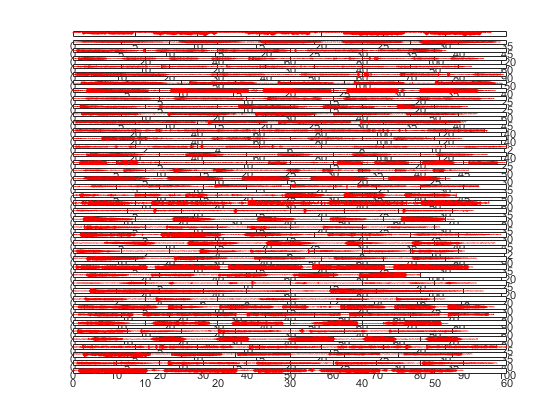

audio_files = dir("grouped_unpackd_audio/aaa");
audio_files(1:2)=[]
all_fns = {audio_files(:).name};

figure;
for k=1:length(all_fns)
    filename = all_fns{k};
    [sig, fs] = audioread(filename);
    t = (1:length(sig))/fs;
    
    subplot(length(all_fns), 1, k);
    plot(t, sig, 'r', 'LineWidth',0.5);
end